After solving the problem of a generally loaded wedge, we try to look into a special problem of **Notch and Crack Problem**. In the generally loaded wedge, we saw that there is no solution for $\sin \left(2\alpha \right)=0$ and $\tan \left(2\alpha \right)=2\alpha$. The problem of crack can be thought of that as a wedge, however $\alpha \approx 0$. Thus we need to modify the entire formulation and derive stress field out of it.

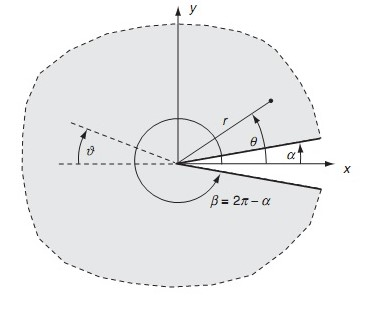

clc; clear all; close all;
warning('off','all');
evalc('WedgeProblem');          % Change n_value in WedgeProblem code for appropriate result.
syms A B C D;

The simplified **Stress Function**, $\phi_{\textrm{ob}}$ can be written as-

phi_ob = collect(simplify(phi_ob),[cos(lambda*theta),sin(lambda*theta),cos((lambda+2)*theta),sin((lambda+2)*theta)]);
disp(phi_ob);

$$\left(r^{\lambda +2}\,\left(A_{1}+A_{2}\right)\right)\,\cos\left(\lambda \,\theta \right)+\left(-r^{\lambda +2}\,\left(A_{1}\,\mathrm{i}-A_{2}\,\mathrm{i}\right)\right)\,\sin\left(\lambda \,\theta \right)+\left(r^{\lambda +2}\,\left(A_{3}+A_{4}\right)\right)\,\cos\left(\theta \,\left(\lambda +2\right)\right)+\left(r^{\lambda +2}\,\left(A_{3}\,\mathrm{i}-A_{4}\,\mathrm{i}\right)\right)\,\sin\left(\theta \,\left(\lambda +2\right)\right)$$

In order to maintain parity with the book *Elasticity by Martin H. Sadd*, we introduce some constants **A, B, C **and **D** and then rewrite the **Stress Function, **$\phi_{\textrm{ob}}$ as $\phi_{\textrm{crack}}$. Also we modify $\lambda$ as $\lambda -2$ at every occurence.

phi_crack = subs(collect(subs(phi_ob,[(A1+A2),(A1*1i-A2*1i),(A3+A4),(A3*1i-A4*1i)],[D,-C,B,A]),r^(lambda+2)),lambda,(lambda-2))

$$phi\_crack = r^{\lambda }\,\left(B\,\cos\left(\lambda \,\theta \right)+A\,\sin\left(\lambda \,\theta \right)+\text{D}\,\cos\left(\theta \,\left(\lambda -2\right)\right)+C\,\sin\left(\theta \,\left(\lambda -2\right)\right)\right)$$

We can find the stress components $\sigma_r ,\sigma_{\theta \;} \;\textrm{and}\;\sigma_{r\theta }$ from the Stress Function, $\phi_{\textrm{crack}}$.

stress = polarStressMatrix(phi_crack);
sigma_r = collect(simplify(stress(1,1)),[cos(lambda*theta),sin(lambda*theta),cos((lambda+2)*theta),sin((lambda+2)*theta)])

$$sigma\_r = \begin{array}{l} \left(-B\,\lambda \,r^{\lambda -2}\,\left(\lambda -1\right)\right)\,\cos\left(\lambda \,\theta \right)+\left(-A\,\lambda \,r^{\lambda -2}\,\left(\lambda -1\right)\right)\,\sin\left(\lambda \,\theta \right)+r^{\lambda -2}\,\left(\lambda -1\right)\,\left(4\,\text{D}\,\sigma_{2}+4\,C\,\sigma_{1}-\text{D}\,\lambda \,\sigma_{2}-C\,\lambda \,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta \,\left(\lambda -2\right)\right)\\ \sigma_{2}=\cos\left(\theta \,\left(\lambda -2\right)\right) \end{array}$$

sigma_t = simplify(stress(2,2))

$$sigma\_t = \lambda \,r^{\lambda -2}\,\left(\lambda -1\right)\,\left(B\,\cos\left(\lambda \,\theta \right)+A\,\sin\left(\lambda \,\theta \right)+\text{D}\,\cos\left(\theta \,\left(\lambda -2\right)\right)+C\,\sin\left(\theta \,\left(\lambda -2\right)\right)\right)$$

sigma_rt = simplify(stress(1,2))

$$sigma\_rt = r^{\lambda -2}\,\left(\lambda -1\right)\,\left(2\,C\,\cos\left(\theta \,\left(\lambda -2\right)\right)-2\,\text{D}\,\sin\left(\theta \,\left(\lambda -2\right)\right)-C\,\lambda \,\cos\left(\theta \,\left(\lambda -2\right)\right)+\text{D}\,\lambda \,\sin\left(\theta \,\left(\lambda -2\right)\right)-A\,\lambda \,\cos\left(\lambda \,\theta \right)+B\,\lambda \,\sin\left(\lambda \,\theta \right)\right)$$

We insert the **Stress-Free Boundary condition** i.e $\sigma_{\theta } \;\textrm{and}\;\tau_{r\theta } =0$ at $\alpha =0\;\textrm{and}\;2\pi$.

eq1 = subs(sigma_t, theta,  0)/(lambda*r^(lambda-2)*(lambda-1))   == 0

$$eq1 = B+\text{D}=0$$

B_s = solve(eq1, B)

$$B\_s = -\text{D}$$

eq2 = subs(sigma_rt, theta, 0)/(-r^(lambda-2)*(lambda-1)) == 0

$$eq2 = A\,\lambda -2\,C+C\,\lambda =0$$

A_s = solve(eq2, A)

$$A\_s = \frac{2\,C-C\,\lambda }{\lambda }$$

eq3 = collect(subs(sigma_t,[theta,A,B],[2*pi,A_s,B_s])/(lambda*(lambda-1)*r^(lambda-2)),[C,D]) == 0

$$eq3 = \left(\sin\left(2\,\pi \,\left(\lambda -2\right)\right)-\frac{\sin\left(2\,\pi \,\lambda \right)\,\left(\lambda -2\right)}{\lambda }\right)\,C+\left(\cos\left(2\,\pi \,\left(\lambda -2\right)\right)-\cos\left(2\,\pi \,\lambda \right)\right)\,\text{D}=0$$

eq4 = collect(subs(sigma_rt,[theta,A,B],[2*pi,A_s,B_s])/(-r^(lambda-2)*(lambda-1)),[C,D]) == 0

$$eq4 = \left(\lambda \,\cos\left(2\,\pi \,\left(\lambda -2\right)\right)-2\,\cos\left(2\,\pi \,\left(\lambda -2\right)\right)-\cos\left(2\,\pi \,\lambda \right)\,\left(\lambda -2\right)\right)\,C+\left(2\,\sin\left(2\,\pi \,\left(\lambda -2\right)\right)+\lambda \,\sin\left(2\,\pi \,\lambda \right)-\lambda \,\sin\left(2\,\pi \,\left(\lambda -2\right)\right)\right)\,\text{D}=0$$

M = equationsToMatrix(eq3,eq4,[C,D])

$$M = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1}-\frac{\sin\left(2\,\pi \,\lambda \right)\,\left(\lambda -2\right)}{\lambda } & \sigma_{2}-\cos\left(2\,\pi \,\lambda \right)\\ \lambda \,\sigma_{2}-2\,\sigma_{2}-\cos\left(2\,\pi \,\lambda \right)\,\left(\lambda -2\right) & 2\,\sigma_{1}+\lambda \,\sin\left(2\,\pi \,\lambda \right)-\lambda \,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\pi \,\left(\lambda -2\right)\right)\\ \sigma_{2}=\cos\left(2\,\pi \,\left(\lambda -2\right)\right) \end{array}$$

Solving the determinant of the above matrix, yields an eigenvalue i.e. $\lambda$. From the book *Elasticity by Martin H. Sadd*, we find the value of $\lambda =\frac{3}{2}$.

lambda_c = 3/2;

We determine the **Stress Components**, $\sigma_r ,\sigma_{\theta } \;\textrm{and}\;\sigma_{r\theta }$ based on the value of $\lambda$.

C_s = solve(subs(eq2,lambda,lambda_c),C);
D_s = solve(eq1,D);
sigma_rc = collect(simplify(subs(sigma_r, [lambda,C,D], [lambda_c,C_s,D_s])),[A,B])

$$sigma\_rc = \left(-\frac{3\,\sin\left(\frac{\theta }{2}\right)\,{\cos\left(\frac{\theta }{2}\right)}^{2}+3\,\sin\left(\frac{\theta }{2}\right)}{\sqrt{r}}\right)\,A+\frac{\cos\left(\frac{\theta }{2}\right)-3\,{\cos\left(\frac{\theta }{2}\right)}^{3}}{\sqrt{r}}\,B$$

sigma_tc = collect(simplify(subs(sigma_t, [lambda,C,D], [lambda_c,C_s,D_s])),[A,B])

$$sigma\_tc = \frac{3\,\sin\left(\frac{\theta }{2}\right)\,\left({\cos\left(\frac{\theta }{2}\right)}^{2}-1\right)}{\sqrt{r}}\,A+\frac{3\,\cos\left(\frac{\theta }{2}\right)\,\left({\cos\left(\frac{\theta }{2}\right)}^{2}-1\right)}{\sqrt{r}}\,B$$

sigma_rtc = collect(simplify(subs(sigma_rt, [lambda,C,D], [lambda_c,C_s,D_s])),[A,B])

$$sigma\_rtc = \frac{3\,\cos\left(\frac{\theta }{2}\right)-3\,{\cos\left(\frac{\theta }{2}\right)}^{3}}{\sqrt{r}}\,A+\left(-\frac{\sin\left(\frac{\theta }{2}\right)-3\,{\cos\left(\frac{\theta }{2}\right)}^{2}\,\sin\left(\frac{\theta }{2}\right)}{\sqrt{r}}\right)\,B$$

stress_matrix = [sigma_rc, sigma_rtc; sigma_rtc, sigma_tc];

In fracture mechanics it is normally more convenient to express the stress field in terms of the angle, $\upsilon$.

syms vartheta;
sigma_rc = collect(simplify(subs(sigma_rc,theta,(pi-vartheta))),[A,B])

$$sigma\_rc = \left(-\frac{6\,\cos\left(\frac{\vartheta }{2}\right)-3\,{\cos\left(\frac{\vartheta }{2}\right)}^{3}}{\sqrt{r}}\right)\,A+\left(-\frac{2\,\sin\left(\frac{\vartheta }{2}\right)-3\,{\cos\left(\frac{\vartheta }{2}\right)}^{2}\,\sin\left(\frac{\vartheta }{2}\right)}{\sqrt{r}}\right)\,B$$

sigma_tc = collect(simplify(subs(sigma_tc,theta,(pi-vartheta))),[A,B])

$$sigma\_tc = \left(-\frac{3\,{\cos\left(\frac{\vartheta }{2}\right)}^{3}}{\sqrt{r}}\right)\,A+\left(-\frac{3\,{\cos\left(\frac{\vartheta }{2}\right)}^{2}\,\sin\left(\frac{\vartheta }{2}\right)}{\sqrt{r}}\right)\,B$$

sigma_rtc = collect(simplify(subs(sigma_rtc,theta,(pi-vartheta))),[A,B])

$$sigma\_rtc = \frac{3\,\cos\left(\frac{\vartheta }{2}\right)\,\sin\left(\vartheta \right)}{2\,\sqrt{r}}\,A+\left(-\frac{\cos\left(\frac{\vartheta }{2}\right)\,\left(\frac{3\,\cos\left(\vartheta \right)}{2}-\frac{1}{2}\right)}{\sqrt{r}}\right)\,B$$

With respect to the angle $\vartheta$, it is noted that terms with the A coefficient include symmetric normal stresses, while the remaining terms containing B have antisymmetric behavior. The symmetric terms are normally referred to as opening or mode I behavior, while antisymmetric terms correspond to shear or mode II.

For mode-I, we can write the **Stress Components** as-

sigma_rA = subs(sigma_rc,B,0)

$$sigma\_rA = -\frac{A\,\left(6\,\cos\left(\frac{\vartheta }{2}\right)-3\,{\cos\left(\frac{\vartheta }{2}\right)}^{3}\right)}{\sqrt{r}}$$

sigma_tA = subs(sigma_tc,B,0)

$$sigma\_tA = -\frac{3\,A\,{\cos\left(\frac{\vartheta }{2}\right)}^{3}}{\sqrt{r}}$$

sigma_rtA = subs(sigma_rtc,B,0)

$$sigma\_rtA = \frac{3\,A\,\cos\left(\frac{\vartheta }{2}\right)\,\sin\left(\vartheta \right)}{2\,\sqrt{r}}$$

Similarly for mode-II, we can write the **Stress Components** as-

sigma_rB = subs(sigma_rc,A,0)

$$sigma\_rB = -\frac{B\,\left(2\,\sin\left(\frac{\vartheta }{2}\right)-3\,{\cos\left(\frac{\vartheta }{2}\right)}^{2}\,\sin\left(\frac{\vartheta }{2}\right)\right)}{\sqrt{r}}$$

sigma_tB = subs(sigma_tc,A,0)

$$sigma\_tB = -\frac{3\,B\,{\cos\left(\frac{\vartheta }{2}\right)}^{2}\,\sin\left(\frac{\vartheta }{2}\right)}{\sqrt{r}}$$

sigma_rtB = subs(sigma_rtc,A,0)

$$sigma\_rtB = -\frac{B\,\cos\left(\frac{\vartheta }{2}\right)\,\left(\frac{3\,\cos\left(\vartheta \right)}{2}-\frac{1}{2}\right)}{\sqrt{r}}$$

We try to plot the normalized **Stress Contours** for mode I.

syms x y;
sigma_rA = simplify(subs(sigma_rA,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_rA/A,[-1 1 -1 1],'Fill','on');
title('\sigma_{r}/A');
xlabel('x'); ylabel('y');
sigma_tA = simplify(subs(sigma_tA,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_tA/A,[-1 1 -1 1],'Fill','on');
title('\sigma_{\theta}/A');
xlabel('x'); ylabel('y');
sigma_rtA = simplify(subs(sigma_rtA,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_rtA/A,[-1 1 -1 1],'Fill','on');
title('\sigma_{r\theta}/A');
xlabel('x'); ylabel('y');
sigma_maxA = subs(sqrt((sigma_rA-sigma_tA)^2+(sigma_rtA)^2),A,1);
fcontour(sigma_maxA,[-0.1 0.1 -0.1 0.1],'Fill','on');
title('\sigma_{max}/A');
xlabel('x'); ylabel('y');

Again, we try to plot the normalized **Stress Contours** for mode II.

sigma_rB = simplify(subs(sigma_rB,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_rB/B,[-1 1 -1 1],'Fill','on');
title('\sigma_{r}/B');
xlabel('x'); ylabel('y');
sigma_tB = simplify(subs(sigma_tB,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_tB/B,[-1 1 -1 1],'Fill','on');
title('\sigma_{\theta}/B');
xlabel('x'); ylabel('y');
sigma_rtB = simplify(subs(sigma_rtB,[r,vartheta],[sqrt(x^2+y^2),atan(y/x)]));
fcontour(sigma_rtB/B,[-1 1 -1 1],'Fill','on');
title('\sigma_{r\theta}/B');
xlabel('x'); ylabel('y');
sigma_maxB = subs(sqrt((sigma_rB-sigma_tB)^2+(sigma_rtB)^2),B,1);
fcontour(sigma_maxB,[-0.1 0.1 -0.1 0.1],'Fill','on');
title('\sigma_{max}/B');
xlabel('x'); ylabel('y');

strain = polarStrainMatrix_Stress([sigma_rz, sigma_rtz; sigma_rtz, sigma_tz]);
epsilon_r  = collect(strain(1,1),[A,B])
epsilon_t  = collect(strain(2,2),[A,B])
epsilon_rt = collect(strain(1,2),[A,B])
